# Введение в интерполяцию

Допустим у нас есть набор данных 

clearvars
N = 5

N = 5

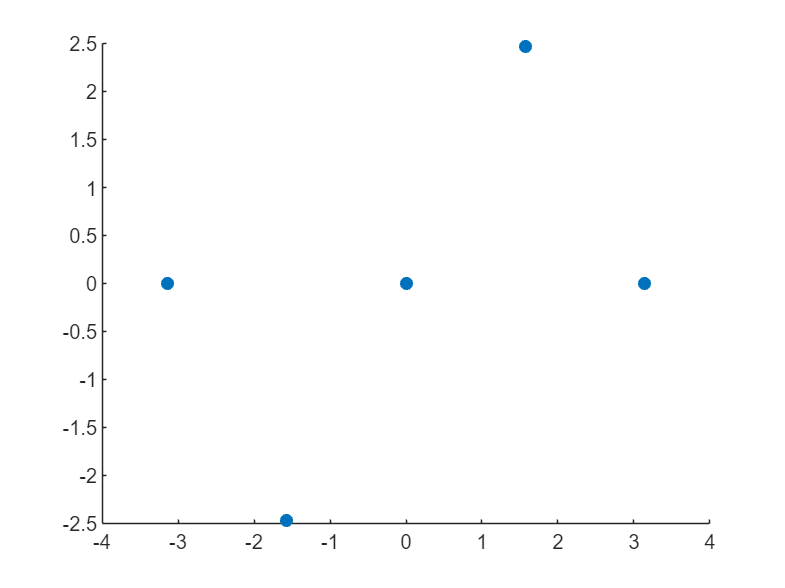

x = linspace(-pi, pi,N);
y = @(x) sin(x).*x.^2;
scatter(x,y(x), MarkerFaceColor="flat")

Задача состоит в том, чтобы заполнить недостающие данные между известными точками. 

Самый общий метод, использующийся для этой задачи это полиномиальная интерполяция. 

Общая формула для степени $(n-1)$ может быть записана как 


$$f(x) = a_1+a_2x+a_3x^2+...+a_nx^{n-1}$$


В матлабовской реализации эта сумма записывается в обратном порядке 


$$f(x) = p_nx^{n-1}+p_2x^{n-2}+...+p_{n-1}x+p_n$$


полиномиальная интерполяция состоит в определении $(n-1)$ полиномов которые опишут n экспериментальных точек.

В нашем случае у нас N точек. 

Попробуем решить задачу "в лоб"


$$\pmatrix{x_1^{n-1} & x_1^{n-2} & ...&x_1&1

\cr 
...
\cr 
x_n^{n-1} & x_n^{n-2} & ...&x_n&1
}

\pmatrix{
p_1
\cr 
...
\cr 
p_n
}
=
\pmatrix{
f(x_1)
\cr 
...
\cr 
f(x_n)
}$$


или можно записать так 


$$Xp=F$$


Матрицу X получим с помощью функции `vander`

X = vander(x)

X =    97.4091  -31.0063    9.8696   -3.1416    1.0000
    6.0881   -3.8758    2.4674   -1.5708    1.0000
         0         0         0         0    1.0000
    6.0881    3.8758    2.4674    1.5708    1.0000
   97.4091   31.0063    9.8696    3.1416    1.0000


Решить данное матричное уравнение можно через стандартный для матлаба способ "\"

p = X\y(x)'

p =     0.0000
   -0.2122
   -0.0000
    2.0944
         0


Посчитаем значение нашей функции с полученными коэффициентами (воспользуемся функцией `polyval`)

x_s = linspace(-pi,pi,N*N);
y_s = polyval(p,x_s)

y_s =    -0.0000   -0.9634   -1.6754   -2.1590   -2.4369   -2.5321   -2.4674   -2.2656   -1.9496   -1.5421   -1.0662   -0.5445         0    0.5445    1.0662    1.5421    1.9496    2.2656    2.4674    2.5321    2.4369    2.1590    1.6754    0.9634    0.0000


Нарисуем графики исходных точек и получившегося полинома

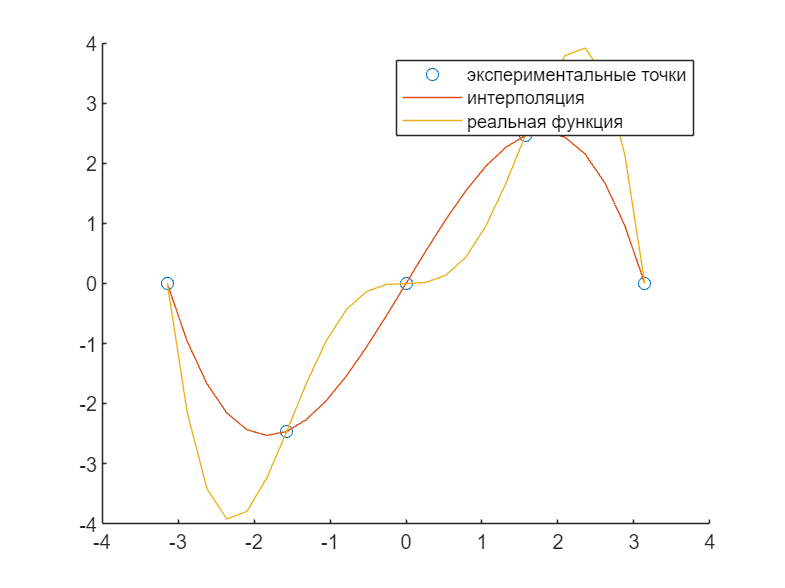

scatter(x,y(x), DisplayName="экспериментальные точки")
hold on
plot(x_s,y_s, DisplayName="интерполяция")
plot(x_s,y(x_s), DisplayName="реальная функция")
legend
hold off

Вроде все хорошо, но давайте посчитаем число обусловленности. Оно получается достаточно высокое. Это неудивительно, так как мы имеем дело с матрицей Вандермонда, а она "плохо обусловлена". Это значит, что решение будет очень сильно зависеть от ошибок округления.

cond(X)

ans = 157.7070

Матлабовская реализация возможна с помощью функции `polyfit `Результат такой же как и наш "ручной". С функцией `polyval` мы познакомились ранее

disp(polyfit(x,y(x),N-1))

   -0.0000   -0.2122    0.0000    2.0944         0



disp(p')

    0.0000   -0.2122   -0.0000    2.0944         0



# Интерполяционные формулы Ньютона

Существует много альтернативных формул для интерполяции. Ньютоновская интерполяция является одной из самых популярных и полезных форм. 

Давайте сначала разберемся с формулами первого и второго порядка для наглядности

## Линейная интерполяция


$$\frac{f_1(x)-f(x_1)}{x-x_1} = \frac{f(x_2)-f(x_2)}{x_2-x_1}$$


Выразим $f_1(x)$

$f_1(x) = f(x_1) + \frac{f(x_2)-f(x_1)}{x_2-x_1}(x-x_1)$ Это линейная интерполяционная формула Ньютона.  Индекс единички  у $f_1(x)$ значит, что у нас интерполяционный полином первого порядка

### Пример

сделаем линейную интерполяцию для функции логарифма по полученной формуле.  

clearvars
x_1 = 1.7;
x_2 = 4.6;
x = [x_1, x_2]; % две точки 1 и 6
f = @(x) log(x); 


% воспользуемся формулой f_1(x)
f_1 = @(x,y) f(x(1))+(f(x(2))-f(x(1)))/(x(2)-x(1))*(y-x(1));

disp(["Вычисленное значение",f_1(x,2), "Реальное значение", log(2), "ошибка:",(abs(f_1(x,2)-log(2))/log(2))*100])

    "Вычисленное значе…"    "0.6336"    "Реальное значение"    "0.69315"    "ошибка:"    "8.5903"



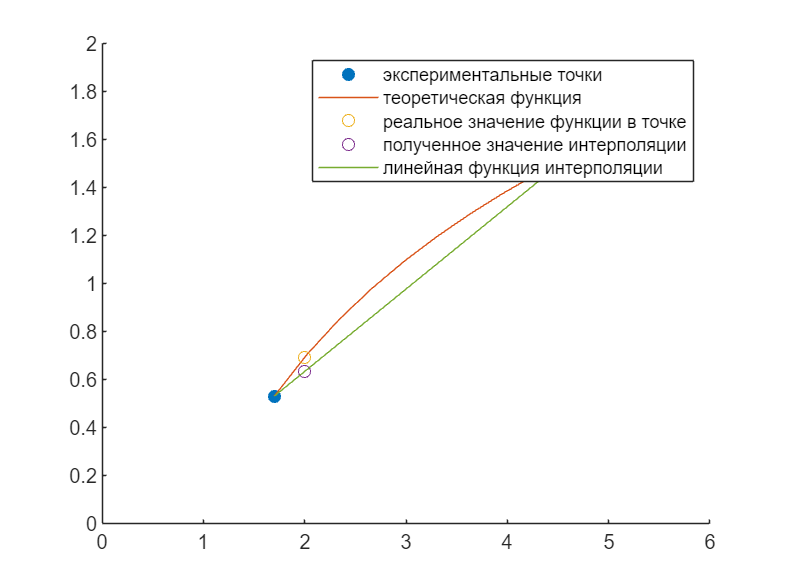



scatter(x,f(x), MarkerFaceColor="flat", DisplayName="экспериментальные точки");
hold on
plot(linspace(x_1,x_2,10),f(linspace(x_1,x_2,10)), DisplayName="теоретическая функция")
scatter(2,log(2),DisplayName="реальное значение функции в точке")
scatter(2,f_1(x,2),DisplayName="полученное значение интерполяции")
legend
plot(x,f(x),DisplayName="линейная функция интерполяции")
xlim([0,6]);
ylim([0,2]);
hold off

### квадратичная интерполяция

Ошибки возникающие для линейной интерполяции складываются из того, что у нас по сути прямая линия. Снизить ошибку можно за счет введения некой кривизны. 

Если имеются 3 точки, то через них мы можем построить параболу (полиномы второго порядка). 

Запишем формулу для такой параболы следующим способом:


$$f_2= b_1+b_2(x-x_1)+b_3(x-x_1)(x-x_2)$$


Найдем коэффициенты b

Подставим x вместо $x_1$


$$f_2(x_1) = b_1+b_2(x_1-x_1)+b_3(x_1-x_1)= b_1+b_2\cdot 0 +b_3 \cdot 0 = b_1$$


Аналогично можно сделать для других коэффициентов 

При $x = x_2$


$$f_2(x_2) = f_2(x_1)+b_2(x_2-x_1)+b_3(x_2-x_2) = f_2(x_1)+b_2(x_2-x_1)+b_3(x_2-x_1)(x_2-x_2) = f_2(x_1)+b_2(x_2-x_1)$$



$$b_2 = \frac{f_2(x_2)-f_2(x_1)}{x_2-x_1}$$


ну и третий коэффициент находится подобным образом 


$$b_3 = \frac{\frac{f_2(x_3)-f_2(x_2)}{x_3-x_2}-\frac{f_2(x_2)-f_2(x_1)}{x_2-x_1}}{x_3-x_1}$$


### Пример

сделаем квадратичную интерполяцию (Ньютоновская интерполяция второго порядка), чтобы получить значение ln2, если известны три промежуточные точки 

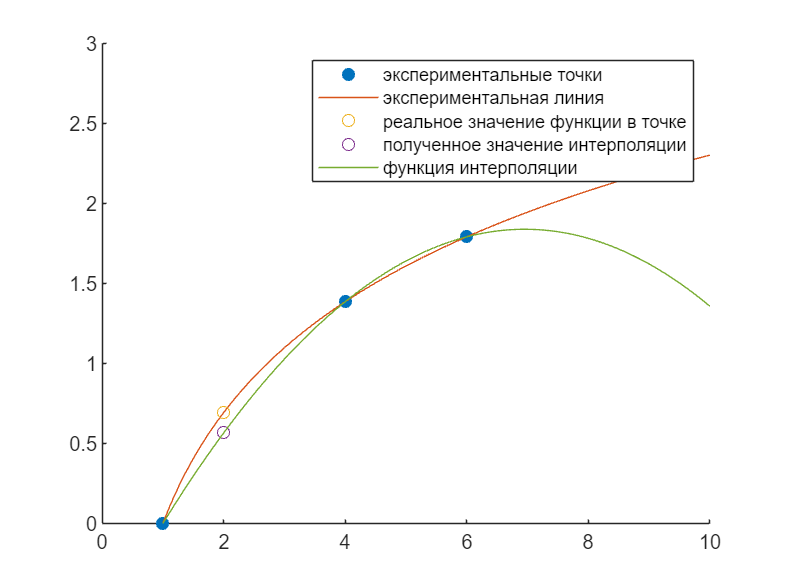

clearvars;
x_1 = 1;
x_2 = 4;
x_3 = 6;
x = [x_1,x_2,x_3];
y = @(x) log(x); % наша функция
f2 = y([x_1,x_2,x_3]); 
b_1 = y(1); 
b_2 = (f2(2)-f2(1))/(x_2-x_1);
b_3 = ((f2(3)-f2(2))/(x_3-x_2)-(f2(2)-f2(1))/(x_2-x_1))/(x_3-x_1);
%общий вид нашей функции будет следующий
f_2 = @(x) b_1+b_2.*(x-x_1)+b_3.*(x-x_1).*(x-x_2);

%построим графики 
scatter(x,f2, MarkerFaceColor="flat", DisplayName="экспериментальные точки");
hold on
plot(linspace(1,10,100), log(linspace(1,10,100)),  DisplayName="экспериментальная линия");
scatter(2,log(2),DisplayName="реальное значение функции в точке")

scatter(2,f_2(2),DisplayName="полученное значение интерполяции")
legend
plot(linspace(1,10,100),f_2(linspace(1,10,100)),DisplayName= "функция интерполяции")
xlim([0,10]);
ylim([0,3]);
hold off

## Общая форма интерполяционных многочленов Ньютона

Общая формула для интерполяции полиномом $(n-1)$ степени для n экспериментальных точек выглядит следующим образом 


$$f_{n-1}(x) = b_1 +b_2(x-x_1) +...+b_n(x-x_1)(x-x_2)...(x-x_{n-1}) $$


коэффициенты будут выглядеть следующим образом 


$$b_1 = f(x_1)

$$



$$b_2 = f[x_2,x_1]$$



$$b_3 = f[x_3,x_2,x_1]$$


...


$$b_n = f[x_n,x_{n-1},...,x_2,x_1]$$
 

$f[]$ - обобщенная разность 


$$f[x_i,x_j] = \frac{f(x_i)-f(x_j)}{x_i-x_j}$$



$$f[x_i,x_j,x_k] = \frac{f[x_i,x_j]-f[x_j,x_k]}{x_i-x_k}$$


x = [1 4 6 5]';
y = log(x);
Newtint(x,y,2)

ans = 0.6288

## Интерполяционные многочлены Лагранжа

Запишем функцию для линейной интерполяции следующим образом


$$f(x) = L_1f(x_1)+L_2f(x_2)$$


где 


$$L_1 = \frac{x-x_2}{x_1-x_2}$$



$$L_2 = \frac{x-x_1}{x_2-x_1}$$


function yint = Newtint(x,y,xx)
% Newtint: Newton interpolating polynomial
% yint = Newtint(x,y,xx): Uses an (n − 1)−order Newton
% interpolating polynomial based on n data points (x, y)
% to determine a value of the dependent variable (yint)
% at a given value of the independent variable, xx.
% input:
% x = independent variable
% y = dependent variable
% xx = value of independent variable at which
% interpolation is calculated
% output:
% yint = interpolated value of dependent variable
% compute the finite divided differences in the form of a
% difference table
n = length(x);
if length(y)~=n, error('x and y must be same length'); end
b = zeros(n,n);
% assign dependent variables to the first column of b.
b(:,1) = y(:); % the (:) ensures that y is a column vector.
for j = 2:n
for i = 1:n-j+1
b(i,j) = (b(i+1,j-1)-b(i,j-1))/(x(i+j-1)-x(i));
end
end
% use the finite divided differences to interpolate
xt = 1;
yint = b(1,1);
for j = 1:n-1
xt = xt*(xx-x(j));
yint = yint+b(1,j+1)*xt;
end
end
